logList = parse_log_folder;
labels = ["0.5", "1.0", "2.0", "4.0", "6.0", "8.0"];

## Raw Line Graphs

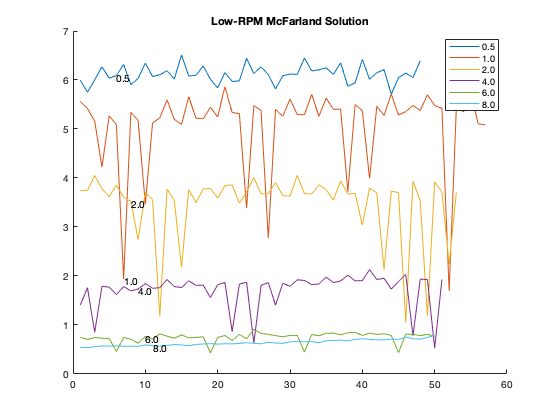

clf;
hold on
for i = 1:size(logList, 2)
    plot(logList(i).data.x630nm)
    text(i+5,logList(i).data.x630nm(5+i)-0.05,labels(i));
end
title("Low-RPM McFarland Solution")
legend(["0.5", "1.0", "2.0", "4.0", "6.0", "8.0"])
hold off

## Moving Average Linegraph

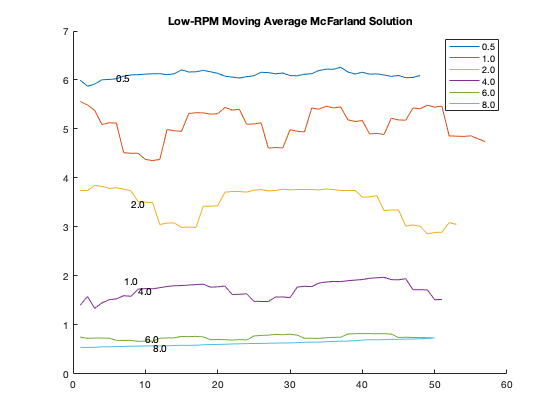

clf;
hold on
for i = 1:size(logList, 2)
    plot(movmean(logList(i).data.x630nm, [5 0]))
    text(i+5,logList(i).data.x630nm(5+i)-0.05,labels(i));
end
title("Low-RPM Moving Average McFarland Solution")
legend(["0.5", "1.0", "2.0", "4.0", "6.0", "8.0"])
hold off

## Statistics

for i = 1:size(logList, 2)
    disp("Statistics for McFarland "+labels(i));
    disp(datastats(logList(i).data.x630nm'));
end

Statistics for McFarland 0.5


       num: 48
       max: 6.5110
       min: 5.7117
      mean: 6.1182
    median: 6.1082
     range: 0.7994
       std: 0.1806



Statistics for McFarland 1.0


       num: 57
       max: 5.8647
       min: 1.6955
      mean: 5.0711
    median: 5.3370
     range: 4.1692
       std: 0.8677



Statistics for McFarland 2.0


       num: 53
       max: 4.0543
       min: 1.0542
      mean: 3.4669
    median: 3.6974
     range: 3.0001
       std: 0.7070



Statistics for McFarland 4.0


       num: 51
       max: 2.1302
       min: 0.5275
      mean: 1.7212
    median: 1.8240
     range: 1.6026
       std: 0.3569



Statistics for McFarland 6.0


       num: 50
       max: 0.9121
       min: 0.4321
      mean: 0.7507
    median: 0.7815
     range: 0.4799
       std: 0.1035



Statistics for McFarland 8.0


       num: 50
       max: 0.7891
       min: 0.5383
      mean: 0.6384
    median: 0.6257
     range: 0.2508
       std: 0.0612

